# Smile Detection Walkthrough

In order to run this code you will need to download `smiles.mat` and make usre that it is in the directory where you are running this livescript.

Note that solutions will be present in a subsequent code block to the one immediately after a question.  You can always check out the solution if you get stuck.  Also, sometimes we will show some cool tricks that we wouldn't expect you to come up with on your own, so the solutions might be good for building your MATLAB knowlege.

**Step 1:** load the data and examine the variables

smiles = load('smiles.mat')

smiles = struct with fields:
     smile_flag_test: [500×1 double]
    smile_flag_train: [19685×1 double]
           test_data: [24×24×500 double]
          train_data: [24×24×19685 double]


We've taken the original dataset and partitioned it into two sets: a training set and a test set.  For each of these sets there is a variable that contains the images (e.g., `train_data`) and another variable (e.g., `smile_flag_train`) that contains whether or not the person in the corresponding image is smile (1) or not smiling (0).

To understand this a little better, let's visualize some of the images and the corresponding smile status.  Use the imshow command to examine a few images of train_data and investigate the corresponding element of the smile_flag_train variable.

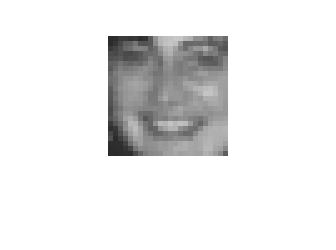

% Solution

% Note: to see the image more clearly, consider popping out
% the image as a figure and expanding the window to zoom in
imshow(smiles.train_data(:,:,1),'InitialMagnification',500);


% to display the smile status, you could do the following
smiles.smile_flag_train(1)

ans = 1


% to make it more readable, you could assign it to a variable
smileStatus = smiles.smile_flag_train(1)

smileStatus = 1


% if you want to be even fancier, you could use disp
disp(['Smile status of image = ', num2str(smiles.smile_flag_train(1))]);

Smile status of image = 1


Fancy version

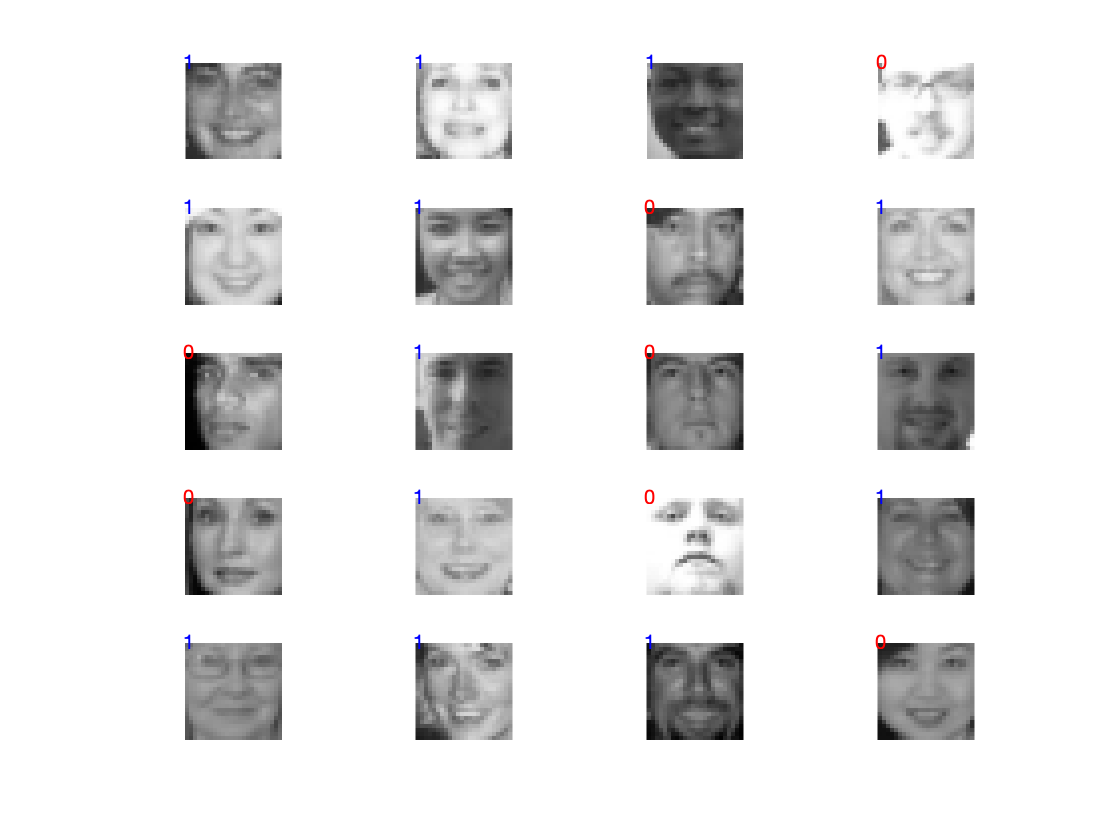

% Fancy solution

% always use figure to create a new plot (otherwise, you may wind up
% editing a previous plot from a prior cell in the notebook).
figure;
% we can use subplot to make a grid of images
imageRows = 5;
imageColumns = 4;

% loop through the first imageRows*imageColumns images
for i = 1 : imageRows*imageColumns
    % switch to out new subplot
    subplot(imageRows, imageColumns, i);
    
    % extract the 24 by 24 pixel matrix and display it at 3x zoom
    imshow(smiles.train_data(:,:,i), 'InitialMagnification', 300);
    % depending on the expression of the face (1 is for smile 0 is for not
    % smiling), draw a blue 1 or a red 0 above the face.
    if smiles.smile_flag_train(i) == 1
        text(0,0,num2str(smiles.smile_flag_train(i)), 'Color', 'blue');
    else
        text(0,0,num2str(smiles.smile_flag_train(i)), 'Color', 'red');
    end
end

Interestingly, it appears that the persorn in the lower right corner has mistakenly been labeled as not smiling.

**Step 2:** Get your system of linear equations ready!  We know that we'd like to formulate the smile detection problem as a system of linear equations.


$$\mathbf{A}\mathbf{x} = \mathbf{b}$$


Before going any further, let's remember the framing we came up with in earlier today.  We'd like the rows of the matrix **A** to represent vectorized versions of the 24 by 24 pixel face images (this means that each column of the matrix **A** will contain the pixel for each image at a particular location in the image).  For example, the first column of **A** will contain the pixel of each face in the upper lefthand corner (pixel coordinate 1,1).

In the next code block, convert `smiles.train_data` into the appropriate matrix `ATrain`, `smiles.test_data` into `ATest`, `smiles.smile_flag_train` into the appropriate matrix `bTrain`, and `smile.smile_flag_test` into the appropriate matrix `bTest`.  In order to accomplish this, you should make use of the `reshape` function.  You may also need to perform a transpose.

How to know if you are right.

- size(ATrain) should give you 19685 by 576

- size(ATest) should give you 500 by 576

- size(bTrain) should give you 19685 by 1

- size(bTest) should give you 500 by 1

- imshow(reshape(ATrain(1,:), [24 24])) should still display something that looks like a face (if you did the reshape improperly, it's possible to scramble your pixels.

% solution
% Note: we are hard coding to 24 by 24 pixels.  You could remove hard
% coding by using size(smiles.train_data,1) to get number of pixel rows and
% size(smiles.train_data,2) to get number of pixel columns.

% the data is initially 24 by 24 by n (where n is the number of faces)
% we first use reshape to unroll each 24 by 24 image into a 576 dimensional
% vector.  Then we transpose the matrix to get it into the dimensions that
% we want (each row should be a datapoint, not a pixel).
ATrain = reshape(smiles.train_data, [24*24 size(smiles.train_data,3)])';
ATest = reshape(smiles.test_data, [24*24 size(smiles.test_data,3)])';

% the smile labels are already in the right form.
bTrain = smiles.smile_flag_train;
bTest = smiles.smile_flag_test;
figure;

% here, we reverse the process of unrolling the image into a vector by reshaping a 576
% dimensional vector that represents a face into a 24 by 24 face image.  We
% then show it at 5x magnification.
imshow(reshape(ATrain(1,:), [24 24]), 'InitialMagnification', 500);

Step 3: using MATLAB solve for **x** in the following system of linear equations.


$$\mathbf{ATrain}^\top \mathbf{ATrain}~\mathbf{x} = \mathbf{ATrain}^\top \mathbf{bTrain}$$


% Solution

% Remember the backslash operator solves a system of linear
% equations (e.g., A\b solves Ax=b)
w = (ATrain'*ATrain)\(ATrain'*bTrain);

Step 4: compute the accuracy of the model **w** on the training and test data.  Remember that the model **w** specifies a linear combination of the pixel values of each face such that if the model is working well, the linear combination is close to 1 for a smiling face and close to 0 for a not smiling face.

Hint: you will need to convert the continuous value you get from the linear combination of pixels into a binary decision (smile versus not smile).  The greater than operator combined with a threshold value for guessing smile is a good way to do this (it can work on single values or whole vectors).

% Solution
disp('Accuracy on training set');

Accuracy on training set


% ATrain*w gives us a value that tells us how smiley an image.  We use a
% threshold of 0.5 to decide that it is smiley enough to predict smile.
% By comparing it with bTrain we get a new vector that has a 1 if we got
% the corresponding face correct and 0 otherwise.  The mean function then
% simply checks how often we have a 1 versus a 0 (which gives us the
% probability of getting the answer correct)
mean((ATrain*w > 0.5) == bTrain)

ans = 0.9011


% the test set can be handled very similarly
disp('Accuracy on testing set');

Accuracy on testing set


mean((ATest*w > 0.5) == bTest)

ans = 0.9080

Step 5: visualize and interpret the weights.  Recall that the vector **w** is a 576 dimensional object that helps us compute how smiley a face is as a linear combination of the pixel brightnesses of a face image.  In order to understand what the model is doing, we can reshape **w **into a 24 by 24 matrix of coefficients and visualize it as a sort of pseudoimage.  This pseudo image will tell us how we weight a corressponding pixel value when computing how smiley an image is. Instead of having you code this yourselves, we'll give you the code to make this visualization and instead ask you to interpret what the model is doing.

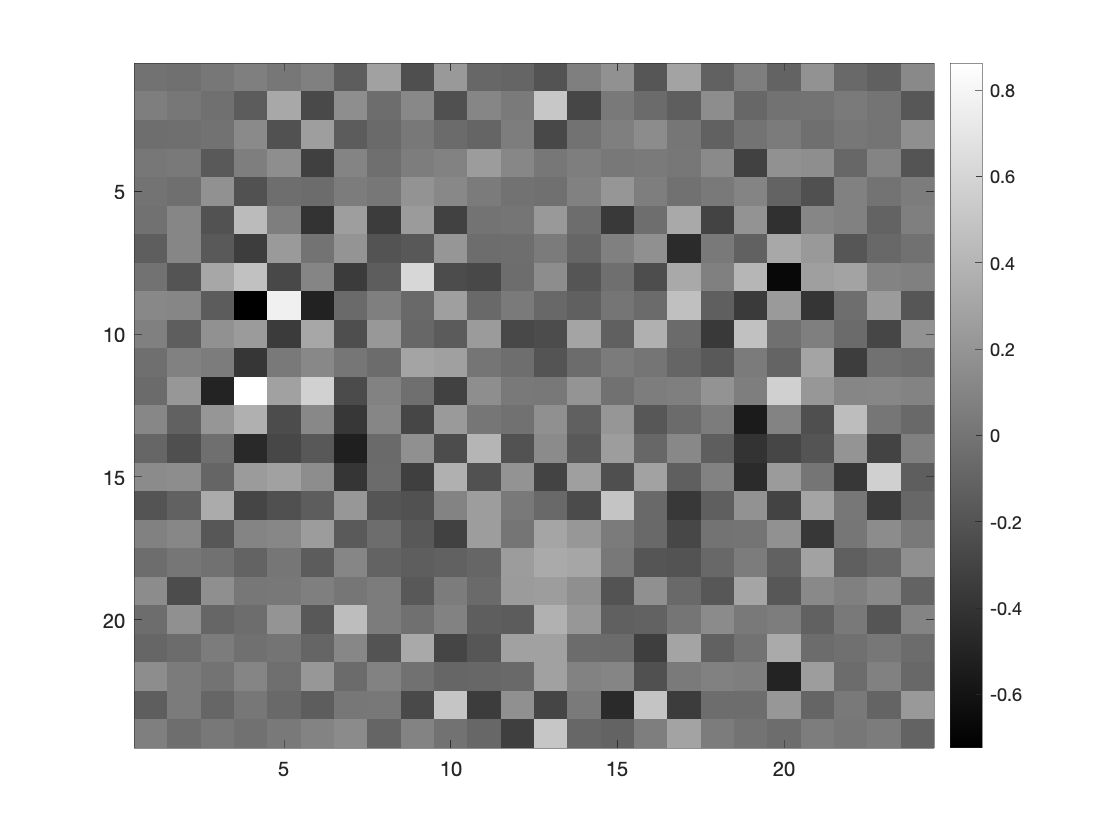

imagesc(reshape(w, [24, 24]));
colormap('gray')
colorbar;

Make sure you understand how this image relates to the predictions of the model.  It may not make all that much sense at the moment (although it does appear that bright pixels near the mouth region correlate to a smilier face).  The reason that the weights in our linear combination of pixels are hard to interpret is due to the phenomenon of overfitting, whereby a machine learning model tunes itself too strongly to the characteristics of the training data,  In the next section, we will see if we can reduce overfitting.

Step 6 (Bonus Fun): reduce overfitting.  There are many ways to reduce overfitting in machine learning.  For models such as the one we are working with here, it is a very common technique to add additional equations to your system that have the effect of pulling the linear combination of pixels closer to 0.  While a full discussion is beyond the scope of this exercise, this technique is called ridge regression.  The basic logic of ridge regression is that in the absence of sufficient data suggesting otherwise, we should prefer to keep the weight on a particular pixel close to 0.

Modify your smile detector by adding a 576 new equations (constraints) to your system `ATrain == bTrain`.  Each one of the new 576 equations should correspond to a particular pixel value in the image.  The corresponding entry in the matrix bTrain should be 0 (encoding that the weight should be pulled towards 0).  Once you add these new equations, you can solve the system as before.

Hint: the simplest method is to stack a 576 dimensional identity matrrix on the bottom of `ATrain` and a 576 by 1 vector of zeros onto `bTrain`.  It turns out that scaling the identiy matrix controls how strongly you pull the weights towards 0, but it should work well just using the identity matrix.

Once you compute your new weight values, visualize the weight vector as an image (using code from previous sections).

See below for solution.

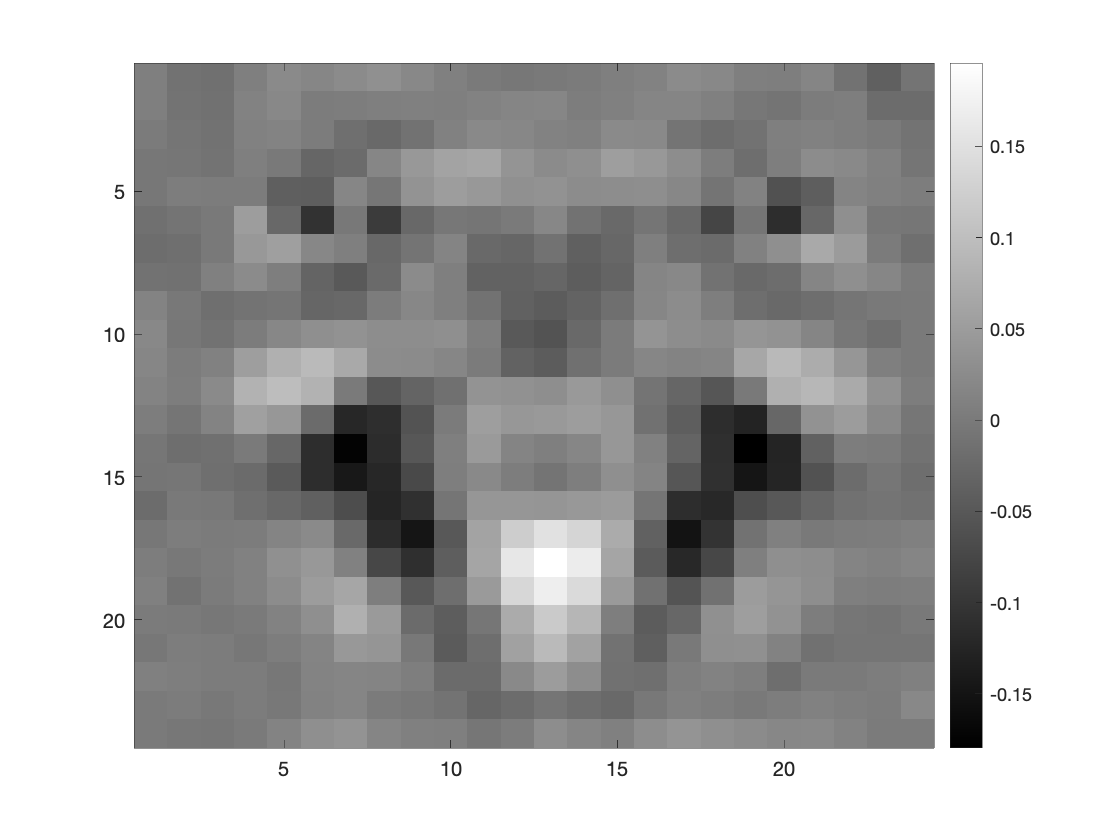

% Solution

% Here we are adding on 576 equations where the ith equation says w_i == 0.
ATrainModified = [ATrain; 0.01*eye(576)];
bTrainModified = [bTrain; zeros(576, 1)];
wModified = (ATrainModified'*ATrainModified)\(ATrainModified'*bTrainModified);

figure;
imagesc(reshape(wModified, [24, 24]));
colormap('gray')
colorbar;